# "Laser scan" line fit example

clear
clc

rosshutdown
setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311','NodeHost','192.168.1.100');

scansub = rossubscriber('/scan');
linescan = receive(scansub); %Receive message
% rangesScan = linescan.Ranges; % Extract scan
% angles = linescan.AngleMin:linescan.AngleIncrement:linescan.AngleMax;

scan = linescan

scan =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -0.5106
          AngleMax: 0.5106
    AngleIncrement: 0.0016
     TimeIncrement: 0
          ScanTime: 0.0330
          RangeMin: 0.4500
          RangeMax: 10
            Ranges: [640×1 single]
       Intensities: [0×1 single]

  Use showdetails to show the contents of the message



ranges = scan.Ranges;
angles = scan.readScanAngles;
size(ranges)

ans =    640     1


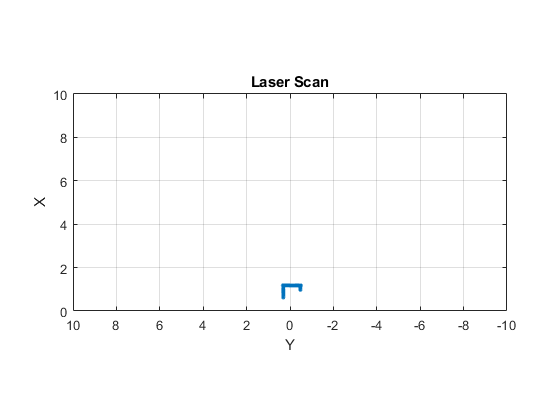


plot(scan)

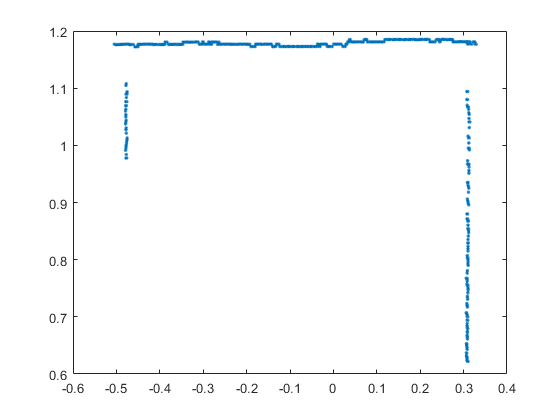


% get data from scan
cart = readCartesian(scan);
figure()
plot(cart(:,2), cart(:,1), '.') % note - y before x..


x = cart(:,2); % x-pos
d = cart(:,1); % depth

## Fitting one line..

% only left side
xleft = x(100:200)
dleft = d(100:200)
plot(xleft, dleft, '.')

mdl = fitlm(xleft,dleft);
coef=mdl.Coefficients.Estimate

plot(x,d, '.'), hold on
plot(x, coef(1) + coef(2)*x, 'r')

## Multi-line method..

N = 200 % grid size

N = 200


xoffset = min(x)

xoffset = -0.5048

xscale = (max(x)-min(x))

xscale = 0.8337

xi = (x - xoffset)/xscale; % scale to 0-1
xi = round(xi*(N-1))+1; % scale and integer 1 to N
di = (d - min(d))/(max(d)-min(d)); % scale to 0-1
di = round(di*(N-1))+1;
ind = sub2ind([N N], xi, di) % matrix indices

ind =        25207
       25208
       25608
       26007
       26407
       26607
       26808
       27008
       27208
       27408


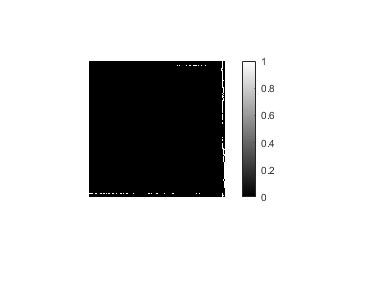


mat = zeros(N); % NxN matrix
mat(ind) = 1; % with points..

imshow(mat), colorbar()

## Hough transform

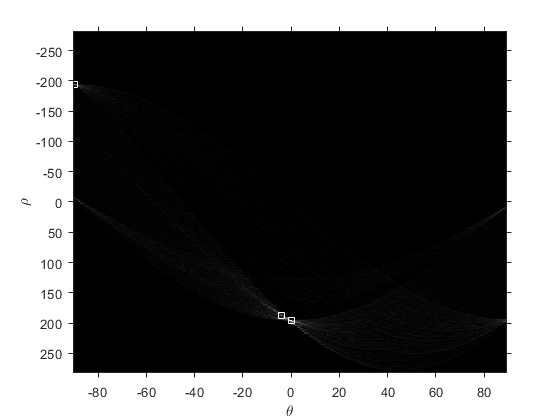

[H,theta,rho] = hough(mat);

% Hough peaks
Nlines = 10; % Note - Nlines peaks/lines !
P  = houghpeaks(H,Nlines); 
imshow(H,[],'XData',theta,'YData',rho,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
plot(theta(P(:,2)),rho(P(:,1)),'s','color','white');

## Hough lines

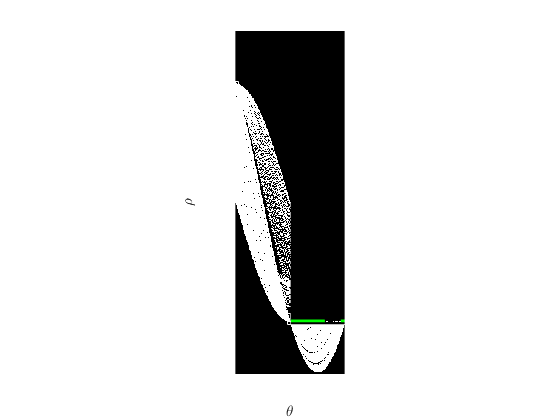

lines = houghlines(mat,theta,rho,P,'FillGap',5,'MinLength',7);

imshow(mat), hold on,
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end


lines(3)

ans = struct with fields:
    point1: [197 113]
    point2: [197 129]
     theta: 0
       rho: 196
